clear all;

Destruction of the object.


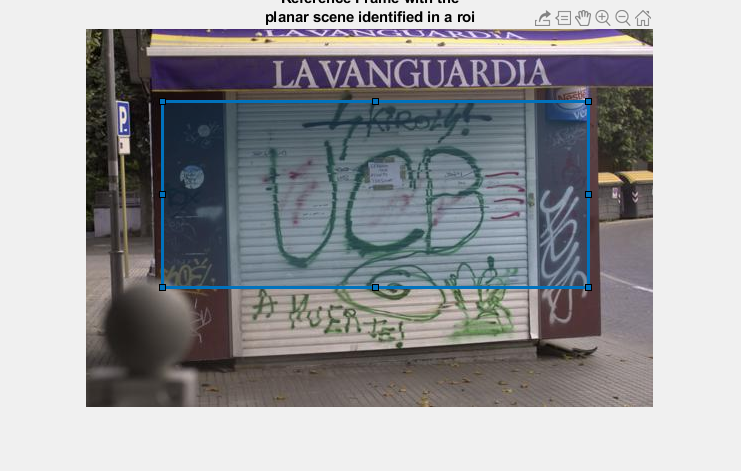

call =   Rectangle with properties:

         Position: [77 73 426 186]
    RotationAngle: 0
      AspectRatio: 0.4366
            Label: ''
            Color: [0 0.4470 0.7410]
           Parent: [1×1 Axes]
          Visible: 'on'
         Selected: 0

  Show all properties


ref = imread("calibrated1.jpg");
% plots
figure, imshow(ref);title("Reference Frame with the"+...
    newline + "planar scene identified in a roi")
% Definition of the planar scene in the reference frame
call = drawrectangle

planar_roi = call.Position;

% homography
theta = 10;
H = projective2d([cosd(theta) -sind(theta) 0; sind(theta) cosd(theta) 0; 0 0 1])

H =   projective2d with properties:

                 T: [3×3 double]
    Dimensionality: 2


H.T

ans =     0.9848   -0.1736         0
    0.1736    0.9848         0
         0         0    1.0000


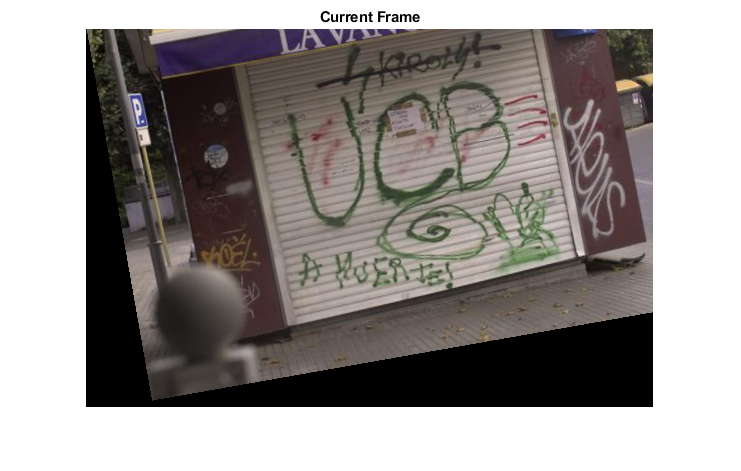

% current frame
curr = imwarp(ref,H,'OutputView', imref2d(size(ref)));
figure, imshow(curr);title("Current Frame");

% Estimate of the homography, with a small error
%Hk = projective2d(inv(H.T));
theta = -10 + 1;
Hk = projective2d([cosd(theta) -sind(theta) 0; sind(theta) cosd(theta) 0; 0 0 1]);

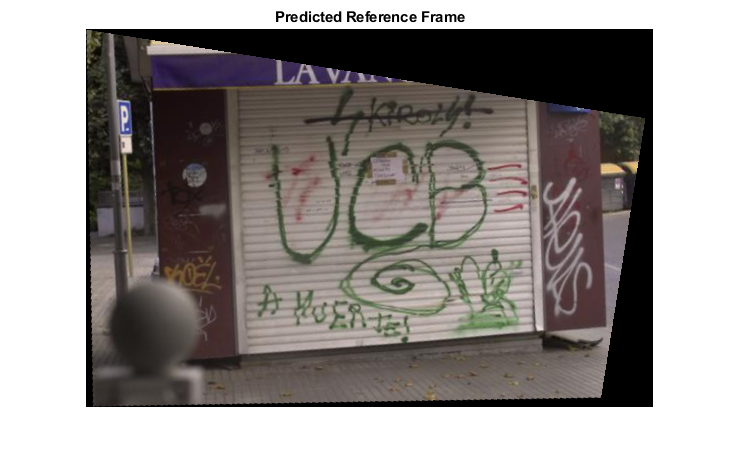

% Observation 

% Prediction of the reference frame
ref_pred = imwarp(curr,Hk,'OutputView', imref2d(size(curr)));
figure, imshow(ref_pred);title("Predicted Reference Frame");

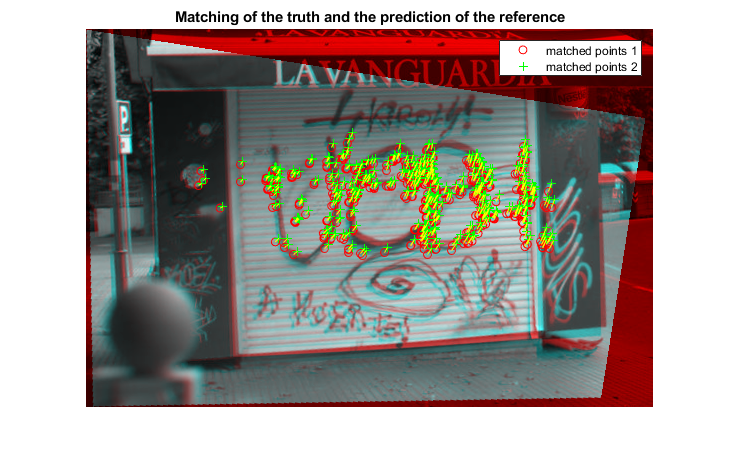

% Features extraction, measurements

% conversion to grayscale
ref_g = rgb2gray(ref);
ref_pred_g = rgb2gray(ref_pred);
% ORB keypoints detection
points_ref = detectORBFeatures(ref_g,'ROI',planar_roi);
points_ref_pred = detectORBFeatures(ref_pred_g,'ROI',planar_roi);
% Extraction of the features
[features_ref, valid_points_ref] = extractFeatures(ref_g, points_ref);
[features_ref_pred, valid_points_ref_pred] = extractFeatures(ref_pred_g, points_ref_pred);
% Matching
% MAX_RATIO to reduce the number of matches : https://fr.mathworks.com/help/vision/ref/matchfeatures.html
indexPairs = matchFeatures(features_ref,features_ref_pred,'MaxRatio',0.7);
matchedPoints1 = valid_points_ref(indexPairs(:,1),:); % matched features expressed in the reference frame coordinates
matchedPoints2 = valid_points_ref_pred(indexPairs(:,2),:); % matched features expressed in the predicted reference frame coordinates
figure; showMatchedFeatures(ref,ref_pred,matchedPoints1,matchedPoints2);
legend('matched points 1','matched points 2');
title("Matching of the truth and the prediction of the reference");

% Computations of the ei and p0 : pixels coordinates for the innovation
fprintf("Number of points measured : %d.",matchedPoints1.Count);

Number of points measured : 472.

%nb_measures = 16; % number of desired measures, at least 4.
p0 = matchedPoints1.Location(1:end,:)

p0 = 472×2 single matrix
   265   109
   438   118
   246   119
   342   121
   261   124
   440   124
   438   126
   347   129
   255   130
   258   131


p0_pred = matchedPoints2.Location(1:end,:)

p0_pred = 472×2 single matrix
   267   104
   440   111
   248   115
   344   115
   263   119
   442   117
   440   118
   349   123
   257   126
   261   126


% Normalization
[height,width,channels] = size(ref)

height = 378

width = 567

channels = 3

p0 = (p0-1-[width/2 height/2])./[width/2 height/2]

p0 = 472×2 single matrix
   -0.0653   -0.4233
    0.5450   -0.3757
   -0.1323   -0.3704
    0.2063   -0.3598
   -0.0794   -0.3439
    0.5520   -0.3439
    0.5450   -0.3333
    0.2240   -0.3175
   -0.1005   -0.3122
   -0.0899   -0.3069


p0_pred = (p0_pred-1-[width/2 height/2])./[width/2 height/2]

p0_pred = 472×2 single matrix
   -0.0582   -0.4497
    0.5520   -0.4127
   -0.1252   -0.3915
    0.2134   -0.3915
   -0.0723   -0.3704
    0.5591   -0.3810
    0.5520   -0.3757
    0.2310   -0.3492
   -0.0935   -0.3333
   -0.0794   -0.3333


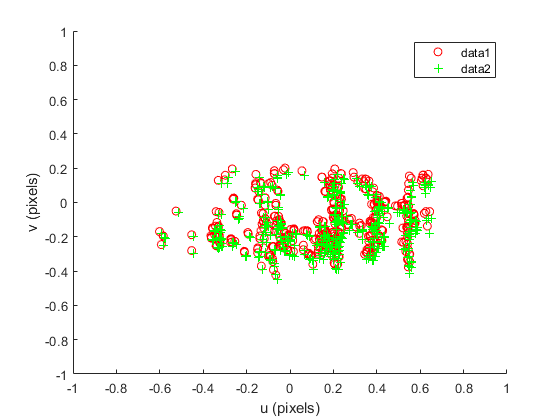


figure, scatter(p0(:,1),p0(:,2),'or');
hold on; scatter(p0_pred(:,1),p0_pred(:,2),'+g')
xlim([-1,1]);ylim([-1,1]);
xlabel('u (pixels)');ylabel('v (pixels)')
legend('show')

% Simple normalization of the pixels, this assumes that the intrinsic
% matrix K = I
p0 = normc(p0')';
p0_pred = normc(p0_pred')';


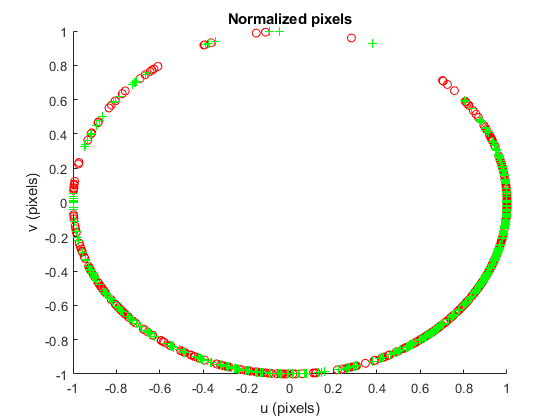

figure, scatter(p0(:,1),p0(:,2),'or');
hold on; scatter(p0_pred(:,1),p0_pred(:,2),'+g')
%xlim([-1,1]);ylim([-1,1]);
xlabel('u (pixels)');ylabel('v (pixels)')
title("Normalized pixels")